clear; clc; close all;

% Load image
image = im2double(imread("images/torsten.png"));

% Define tile size
tileSize = 15;

% Get image dimensions
[rows, cols, channels] = size(image);

% Ensure image size is divisible by tileSize
rows = floor(rows / tileSize) * tileSize;
cols = floor(cols / tileSize) * tileSize;
image = imresize(image, [rows, cols]);

% Create output image
reconstructed = zeros(size(image));

% Create a library of different tile variations (scaled versions of the original)
scales = [0.5, 0.75, 1.0, 1.25, 1.5]; 
tileLibrary = cell(length(scales), 1);

for i = 1:length(scales)
    tileLibrary{i} = imresize(image, scales(i), 'bicubic');
end

% Process each segment
for r = 1:tileSize:rows
    for c = 1:tileSize:cols
        % Extract current image segment
        segment = image(r:r+tileSize-1, c:c+tileSize-1, :);

        bestTile = tileLibrary{1}; % Default tile
        bestScore = -inf; % Initialize lowest SSIM score

        % Find the best-matching tile using SSIM
        for i = 1:length(tileLibrary)
            resizedTile = imresize(tileLibrary{i}, [tileSize, tileSize]); % Resize to match

            % Compute SSIM similarity
            score = ssim(segment, resizedTile);

            % If this tile is a better match, update the best tile
            if score > bestScore
                bestScore = score;
                bestTile = resizedTile;
            end
        end

        % ----- Adjust color and brightness -----
        % Compute the mean color of the original segment and the selected tile
        meanSegment = mean(segment, [1,2]); 
        meanTile = mean(bestTile, [1,2]);

        % Compute color correction factor
        colorCorrection = meanSegment ./ meanTile;

        % Apply color correction
        adjustedTile = bestTile .* colorCorrection;

        % Ensure values remain in the valid range [0,1]
        adjustedTile = min(max(adjustedTile, 0), 1);

        % Replace the segment with the adjusted tile
        reconstructed(r:r+tileSize-1, c:c+tileSize-1, :) = adjustedTile;
    end
end

% ----- SCIElab Comparison -----
CIED65 = [95.05, 100, 108.9]; % White point
d = 40/2.54;       % Viewing distance in cm
ppi = 267;    % Pixels per inch (Surface Pro 6)
sampPerDegree = ppi * d * tan(pi/180); % Calculate sampling rate

% Convert images to XYZ color space
imageXYZ = rgb2xyz(image);
reconstructedXYZ = rgb2xyz(reconstructed);

% Compute SCIElab map
scieMap = scielab(sampPerDegree, imageXYZ, reconstructedXYZ, CIED65, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


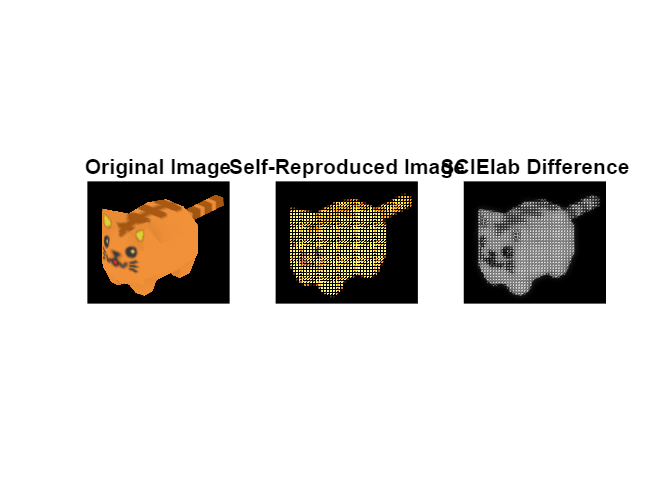


% ----- Compute SNR -----
snrValue = snr(image, image - reconstructed);

% Display results
figure;
subplot(1,3,1); imshow(image); title('Original Image');
subplot(1,3,2); imshow(reconstructed); title('Self-Reproduced Image');
subplot(1,3,3); imshow(scieMap, []); title('SCIElab Difference');


% Print SNR value
disp("SNR (dB): " + snrValue);

SNR (dB): 2.1182


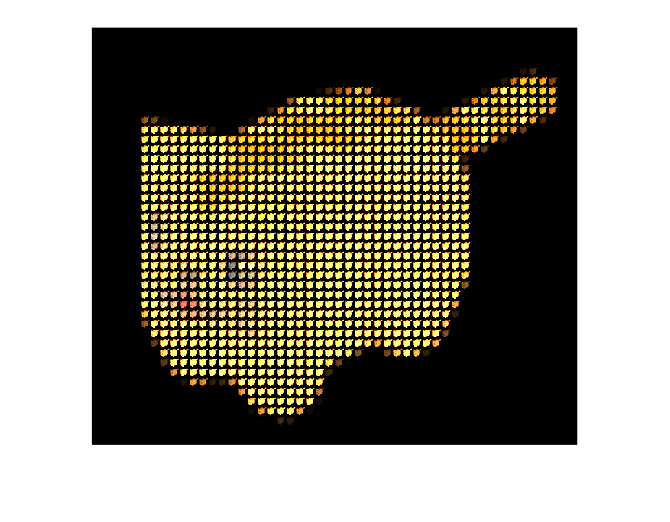

figure;
imshow(reconstructed);